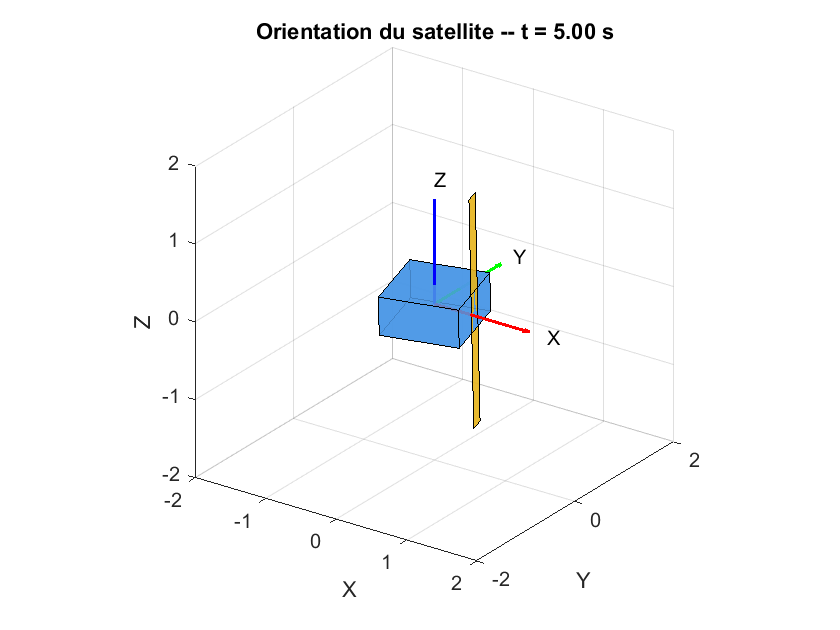

%% anime_satellite.m
% Animation 3D d'un satellite (représenté par un parallélépipède)
% à partir des angles d'Euler psi, theta, phi issus de la simulation Simulink.
%
% PRE-REQUIS :
%   - Dans Simulink, il faut récupérer psi, theta, phi dans le workspace.
%     Le plus simple : ajouter des blocs "To Workspace" sur ces 3 signaux
%     (format "Structure with time" ou "Array"), ou passer par un bloc
%     "Scope" -> clic droit -> "Log data to workspace".
%   - Ici, on suppose que tu as après simulation trois vecteurs colonnes
%     dans le workspace : t (temps), psi_vec, theta_vec, phi_vec,
%     tous de même longueur.
%
% Si tes signaux sont dans une structure "simout" (To Workspace en mode
% "Structure with time"), adapte la section "CHARGEMENT DES DONNEES"
% ci-dessous en conséquence (voir commentaires).

% clear; close all; clc;

%% ============== CHARGEMENT DES DONNEES ==============
% Adapte cette section à ta configuration Simulink.
% Exemple si tu as trois vecteurs simples dans le workspace :
t = out.time;
psi_vec   = out.psi;
theta_vec = out.theta;
phi_vec   = out.phi;


%% ============== PARAMETRES DU SATELLITE (CUBE) ==============
% Dimensions du corps principal du satellite (parallélépipède)
Lx = 1; Ly = 1; Lz = 0.5;

% Sommets du cube centré à l'origine (8 sommets)
vertices0 = [ -Lx/2 -Ly/2 -Lz/2;
               Lx/2 -Ly/2 -Lz/2;
               Lx/2  Ly/2 -Lz/2;
              -Lx/2  Ly/2 -Lz/2;
              -Lx/2 -Ly/2  Lz/2;
               Lx/2 -Ly/2  Lz/2;
               Lx/2  Ly/2  Lz/2;
              -Lx/2  Ly/2  Lz/2 ]';

% Faces du cube (indices des sommets pour chaque face)
faces = [1 2 3 4;   % face bas
         5 6 7 8;   % face haut
         1 2 6 5;   % face avant
         2 3 7 6;   % face droite
         3 4 8 7;   % face arrière
         4 1 5 8];  % face gauche

% Panneau solaire simplifié (un rectangle fin attaché sur un côté)
panel_vertices0 = [ Lx/2   -0.1  -1.5;
                     Lx/2    0.1  -1.5;
                     Lx/2    0.1   1.5;
                     Lx/2   -0.1   1.5]';
panel_face = [1 2 3 4];

%% ============== INITIALISATION DE LA FIGURE ==============
fig = figure('Color','w','Name','Animation satellite');
ax = axes('Parent', fig);
axis(ax, 'equal');
grid(ax, 'on');
xlabel(ax,'X'); ylabel(ax,'Y'); zlabel(ax,'Z');
lim = 2;
xlim(ax,[-lim lim]); ylim(ax,[-lim lim]); zlim(ax,[-lim lim]);
view(ax, 35, 25);
hold(ax, 'on');

% Repère fixe (axes X, Y, Z) pour repère visuel
quiver3(ax,0,0,0,1.5,0,0,'r','LineWidth',1.5); text(1.6,0,0,'X');
quiver3(ax,0,0,0,0,1.5,0,'g','LineWidth',1.5); text(0,1.6,0,'Y');
quiver3(ax,0,0,0,0,0,1.5,'b','LineWidth',1.5); text(0,0,1.6,'Z');

% Objets 3D initiaux (corps + panneau), mis à jour à chaque frame
hBody  = patch('Faces',faces,'Vertices',vertices0','FaceColor',[0.3 0.6 0.9], ...
               'FaceAlpha',0.85,'EdgeColor','k','Parent',ax);
hPanel = patch('Faces',panel_face,'Vertices',panel_vertices0','FaceColor',[0.9 0.7 0.1], ...
               'FaceAlpha',0.9,'EdgeColor','k','Parent',ax);

titleHandle = title(ax, 'Orientation du satellite -- t = 0.00 s');

%% ============== PREPARATION DE L'EXPORT VIDEO ==============
% VideoWriter capture chaque frame une par une et les assemble en .mp4.
% Le fichier sera créé dans le dossier courant sous le nom "satellite_animation.mp4".
vidObj = VideoWriter('satellite_animation.mp4', 'MPEG-4');
vidObj.FrameRate = 20;   % images par seconde dans la vidéo finale
open(vidObj);

%% ============== BOUCLE D'ANIMATION ==============
% On sous-échantillonne si le nombre de points est très grand,
% pour garder une animation fluide.
step = max(1, floor(length(t)/300));

for k = 1:step:length(t)

    psi_k   = psi_vec(k);
    theta_k = theta_vec(k);
    phi_k   = phi_vec(k);

    % Matrice de rotation R(psi, theta, phi), identique à celle
    % de la Partie 1 du TP (rotation Z -> X -> Z, angles d'Euler)
    Rpsi = [ cos(psi_k) -sin(psi_k) 0;
             sin(psi_k)  cos(psi_k) 0;
             0           0          1];

    Rtheta = [1 0            0;
              0 cos(theta_k) -sin(theta_k);
              0 sin(theta_k)  cos(theta_k)];

    Rphi = [ cos(phi_k) -sin(phi_k) 0;
             sin(phi_k)  cos(phi_k) 0;
             0           0          1];

    R = Rpsi * Rtheta * Rphi;

    % Application de la rotation aux sommets du corps et du panneau
    verticesRot = (R * vertices0)';
    panelRot    = (R * panel_vertices0)';

    set(hBody,  'Vertices', verticesRot);
    set(hPanel, 'Vertices', panelRot);
    set(titleHandle, 'String', sprintf('Orientation du satellite -- t = %.2f s', t(k)));

    drawnow;

    % Capture de la frame courante et écriture dans la vidéo
    frame = getframe(fig);
    writeVideo(vidObj, frame);
end


%% ============== FERMETURE DU FICHIER VIDEO ==============
close(vidObj);
fprintf('Vidéo enregistrée : %s\n', fullfile(pwd, 'satellite_animation.mp4'));

Vidéo enregistrée : C:\Users\NAOUE\Desktop\Univ Lille\Satellite\satellite_animation.mp4
